## [Gaussian Process Regression](https://apmonitor.com/pds/index.php/Main/GaussianProcessRegression)

Gaussian process (GP) regression is a type of probabilistic model that can be used for regression tasks. It is a non-parametric method that is based on the assumption that the function to be learned is drawn from a Gaussian process. This assumption allows the model to make predictions with a well-defined uncertainty, which can be useful for tasks such as active learning and uncertainty-aware decision making.

Mathematically, the GP regression model can be written as follows. Let $x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_n$ be the input data points, where $x_i \in R^d$ is a *d*-dimensional vector. Let $y_1 ,y_2 ,\ldotp \ldotp \ldotp ,y_n$ be the corresponding output values, where  is a scalar. The GP regression model assumes that the function *f* that relates the inputs to the outputs is drawn from a Gaussian process with mean function μ and covariance function *k*. The distribution of *f* at a set of test points *x**** is then given by:


$$f\left(x^* \right)\sim N\left(\mu \left(x^* \right),k\left(x^* ,x^* \right)\right)$$


The mean function and covariance function are typically defined using kernel functions. For example, the commonly used squared exponential kernel is defined as:


$$k\left(x_i ,x_j \right)=\exp \left(-\frac{1}{2}{\left\|x_i -x_j \right\|}^2 \right)$$


Given a set of training data *(x, y)*, the GP regression model uses Bayesian inference to learn the distribution of *f* that is most likely to have generated the data. This involves computing the posterior distribution of *f* given the data, which is defined as:


$$p\left(f|x,y\right)=\frac{p\left(y|x,f\right)p\left(f\right)}{p\left(y|x\right)}$$


where $\left(y|x,f\right)$ is the likelihood of the data given the function *f*, $p\left(f\right)$ is the prior distribution of *f*, and $p\left(y|x\right)$ is the marginal likelihood of the data.

Once the posterior distribution of *f* has been learned, the model can make predictions at new test points *x**** by computing the posterior predictive distribution, which is defined as:


$$p\left(f^* |x^* ,y,x\right)=\int p\left(f^* |x^* ,f\right)p\left(f|y,x\right)\;\mathrm{df}$$


This distribution provides a measure of the uncertainty of the prediction, which can be useful for tasks such as active learning and uncertainty-aware decision making.

Gaussian process regression (GPR) uses training data, similar to [**k-Nearest Neighbors**](https://apmonitor.com/pds/index.php/Main/KNearestNeighborsRegression), to make predictions. It works well with small data sets and provides a prediction with uncertainty quantification.

The prior mean and prior covariance must be specified. The covariance is specified as a kernel object. The kernel hyper-parameters are optimized during fitting by maximizing the log-marginal-likelihood (LML) based on the specified optimizer. This maximization is a non-convex optimization (multiple local optima) so the optimizer is restarted multiple times. The first iteration starts from the initial hyper-parameters and subsequent iterations use randomly selected hyper-parameters within the allowed range.

**Advantages:** Predictions are an interpolation of the training data for regular kernels. The predictions also produce a probability for a confidence interval. GP can use many different kernels or use the default standard kernels.

**Disadvantages:** GP is not efficient when the number of features is greater than ~30. GP is not sparse with all of the features and samples used to perform the prediction.

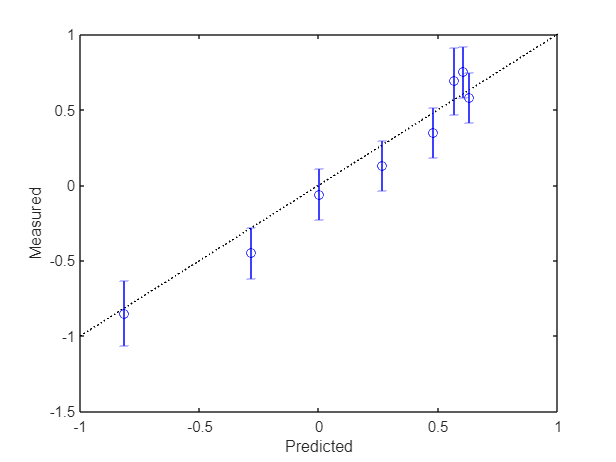

% Training Data
XA =  [4,5,2,3,-1,1,6,7];
yA = [0.3,0.8,-0.05,0.1,-0.8,-0.5,0.5,0.65];
s = fitrgp(XA', yA');

% Test data
XB = [4.5, 5.5, 2.5, 3.5, -1.5, 1.5, 5.9, 7.8];
yB = [0.35, 0.75, -0.06, 0.13, -0.85, -0.45, 0.58, 0.69];
[yP, stdev] = predict(s, XB');

% Plot results
figure;
plot([-1, 1], [-1, 1], 'k:');
hold on;
errorbar(yP, yB, stdev, 'o', 'Color', 'blue');
xlabel('Predicted');
ylabel('Measured');
hold off;